This ver only compares N/F and l1l2-alg.

clc;
clear;
close all;

addpath PROPACK;

% fixed model parameter set
tol = 1e-4;
maxiter = 1000;

% parameters for N/F-ADMM
lembda = 300;
mu1 = 0.1;
mu2 = 0.1;
k_max = 500;
t_max = 5;
tol_nf = 1e-5;

% parameters for l1l2-ADMM
beta_l1l2 = 1;
mu_l1l2 = 10;
rho_l1l2 = 0.2;

% every experiment would be repeated for 10 times
% compute the average and the standard deviation
repeat = 10;

% basic parameters set
% n1 x n2
n1 = 100;
n2 = 100;

% mu
mu = 0.1;
mu_vec = (0.1: 0.05: 0.5)';

% r
r = 10;
r_vec = (6: 2: 20)';

% sr
sr = 0.5;
sr_vec = (0.5: 0.05: 0.9)';

main part of the code

- change mu

- change r

- change sr

%% 1. change mu
% re_mu_**_vec stores the average value(re) and its std of ** for different mu
% 9 below means there are 9 different mus
re_mu_nf_vec = zeros(9, 2);
re_mu_l1l2_vec = zeros(9, 2);

% record the time
time_mu_nf_vec = zeros(9, 1);
time_mu_l1l2_vec = zeros(9, 1);

% index indicates the index of current mu_change
index = 1;

% fun for different mu_changes
for mu_change = 0.1: 0.05: 0.5
    mu_change
    index

    % define re_**_vec
    re_nf_vec = zeros(repeat, 1);
    re_l1l2_vec = zeros(repeat, 1);
    
    % repeat, return the vec
    for i = 1 : repeat
    
        % generating matrix
        L = normrnd(0, 1, n1, r);
        R = normrnd(0, 1, n2, r);
        N = normrnd(0, 1, n1, n2);
        X = L * R' + mu_change * N;
        
        % sampling matrix(support)
        support = ones(n1, n2);
        Ind = randperm(n1 * n2);
        
        %number of missing values
        EL0 = round(n1 * n2 * (1 - sr));
        
        %random EL0 elements would be set to 0
        support(Ind(1:EL0)) = 0;
    
        % observed matrix
        D = support .* X;
    
        % ||X||_F
        X_fro = max(norm(X, 'fro'), 1);

        %% N/F
        % experiment
        start_nf = tic;
        X_nf = NF(D, support, lembda, mu1, mu2, k_max, t_max, tol_nf);
        time_nf = toc(start_nf);
        % time
        time_mu_nf_vec(index, 1) = time_mu_nf_vec(index, 1) + time_nf;

        % re
        re_nf = norm(X_nf - X, 'fro') / X_fro;

        %fill in the re_nf_vec
        re_nf_vec(i, 1) = re_nf;

        %% l1l2
        % experiment
        start_l1l2 = tic;
        X_l1l2 = l1l2(D, support, beta_l1l2, mu_l1l2, rho_l1l2, tol, maxiter);
        time_l1l2 = toc(start_l1l2);
        % time
        time_mu_l1l2_vec(index, 1) = time_mu_l1l2_vec(index, 1) + time_l1l2;

        % re
        re_l1l2 = norm(X_l1l2 - X, 'fro') / X_fro;

        % fill in the re_l1l2_vec
        re_l1l2_vec(i, 1) = re_l1l2;

    end

    % fill in the average re
    re_mu_nf_vec(index, 1) = mean(re_nf_vec);
    re_mu_l1l2_vec(index, 1) = mean(re_l1l2_vec);

    % fill in its std
    re_mu_nf_vec(index, 2) = std(re_nf_vec);
    re_mu_l1l2_vec(index, 2) = std(re_l1l2_vec);

    % normalization for time
    time_mu_nf_vec(index, 1) = time_mu_nf_vec(index, 1) / repeat;
    time_mu_l1l2_vec(index, 1) = time_mu_l1l2_vec(index, 1) / repeat;

    % update index
    index = index + 1;
end

mu_change = 0.1000

index = 1

mu_change = 0.1500

index = 2

mu_change = 0.2000

index = 3

mu_change = 0.2500

index = 4

mu_change = 0.3000

index = 5

mu_change = 0.3500

index = 6

mu_change = 0.4000

index = 7

mu_change = 0.4500

index = 8

mu_change = 0.5000

index = 9

plot for mu (svt, wnnm, splp)

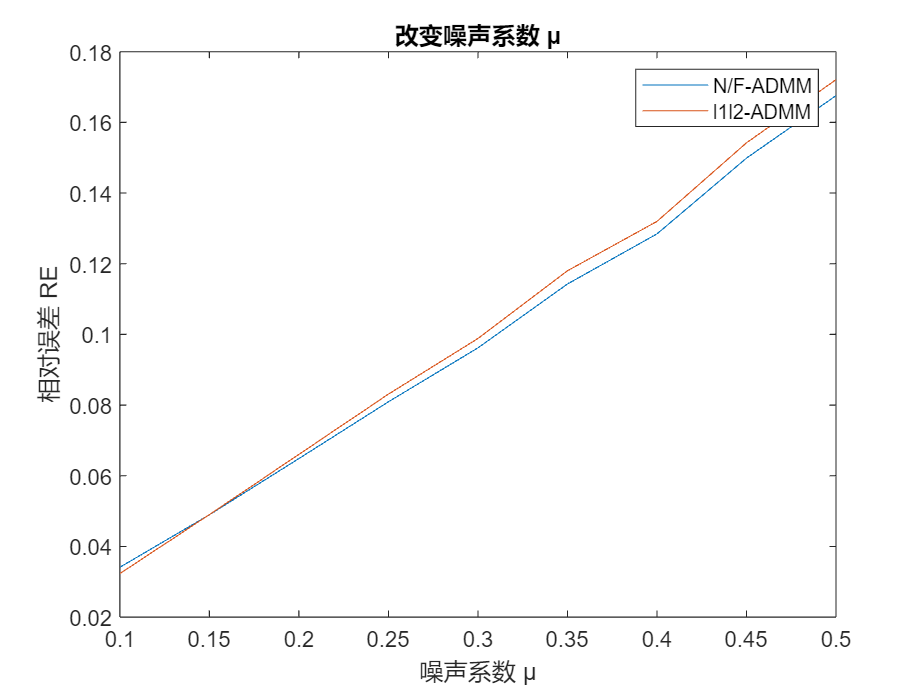

% plot for mu (svt, wnnm, splp)
plot(mu_vec, re_mu_nf_vec(:, 1))
hold on
plot(mu_vec, re_mu_l1l2_vec(:, 1))
hold off
title("改变噪声系数 μ")
xlabel("噪声系数 μ")
ylabel("相对误差 RE")
legend("N/F-ADMM", "l1l2-ADMM")
saveas(gcf, 're-mu-l1l2', 'jpg');

plot for mu time

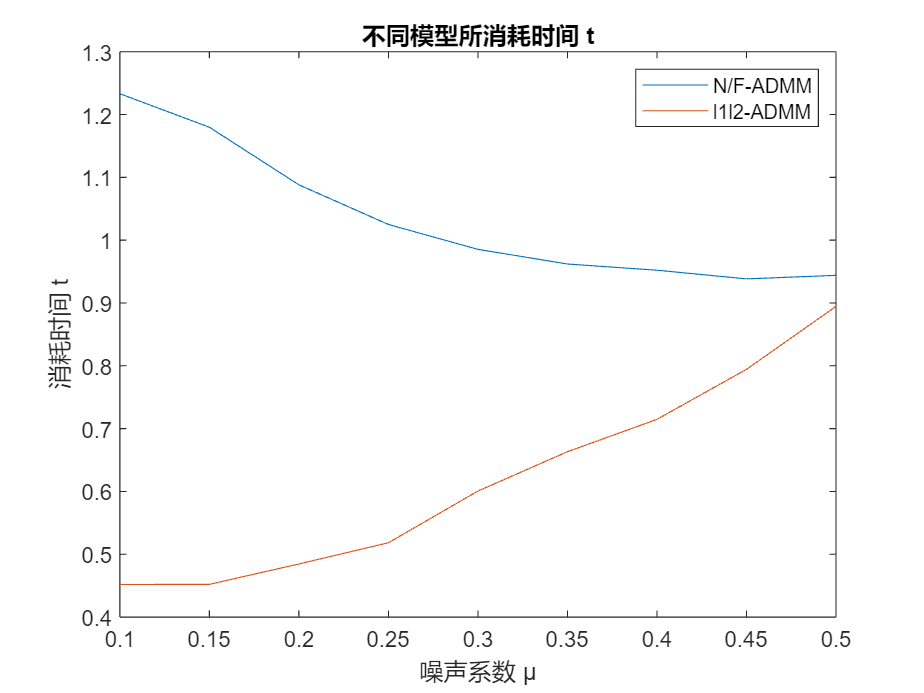

plot(mu_vec, time_mu_nf_vec)
hold on
plot(mu_vec, time_mu_l1l2_vec)
hold off
title("不同模型所消耗时间 t")
xlabel("噪声系数 μ")
ylabel("消耗时间 t")
legend("N/F-ADMM", "l1l2-ADMM")
saveas(gcf, 't-mu-l1l2', 'jpg');

check the result of mu

re_mu_nf_vec

re_mu_nf_vec =     0.0341    0.0010
    0.0490    0.0016
    0.0649    0.0034
    0.0809    0.0028
    0.0962    0.0033
    0.1143    0.0047
    0.1284    0.0048
    0.1499    0.0059
    0.1676    0.0051


re_mu_l1l2_vec

re_mu_l1l2_vec =     0.0323    0.0008
    0.0490    0.0016
    0.0661    0.0034
    0.0831    0.0030
    0.0988    0.0034
    0.1180    0.0050
    0.1320    0.0053
    0.1542    0.0064
    0.1721    0.0052


2. change r

%% 2. change r
% re_r_**_vec stores the average value(re) of ** for different r(rank)
% 8 different ranks
re_r_nf_vec = zeros(8, 2);
re_r_l1l2_vec = zeros(8, 2);

% time
time_r_nf_vec = zeros(8, 1);
time_r_l1l2_vec = zeros(8, 1);

% index indicates the index of current r_change
index = 1;

% fun for different r_changes
for r_change = 6: 2: 20
    r_change
    index

    % define re_**_vec
    re_nf_vec = zeros(repeat, 1);
    re_l1l2_vec = zeros(repeat, 1);
    
    % repeat, return the vec
    for i = 1 : repeat
    
        % generating matrix
        L = normrnd(0, 1, n1, r_change);
        R = normrnd(0, 1, n2, r_change);
        N = normrnd(0, 1, n1, n2);
        X = L * R' + mu * N;
        
        % sampling matrix(support)
        support = ones(n1, n2);
        Ind = randperm(n1 * n2);
        
        %number of missing values
        EL0 = round(n1 * n2 * (1 - sr));
        
        %random EL0 elements would be set to 0
        support(Ind(1:EL0)) = 0;
    
        % observed matrix
        D = support .* X;
    
        % ||X||_F
        X_fro = max(norm(X, 'fro'), 1);
    
        %% N/F
        % experiment
        start_nf = tic;
        X_nf = NF(D, support, lembda, mu1, mu2, k_max, t_max, tol_nf);
        time_nf = toc(start_nf);
        % time
        time_r_nf_vec(index, 1) = time_r_nf_vec(index, 1) + time_nf;

        % re
        re_nf = norm(X_nf - X, 'fro') / X_fro;

        %fill in the re_nf_vec
        re_nf_vec(i, 1) = re_nf;

        %% l1l2
        % experiment
        start_l1l2 = tic;
        X_l1l2 = l1l2(D, support, beta_l1l2, mu_l1l2, rho_l1l2, tol, maxiter);
        time_l1l2 = toc(start_l1l2);
        % time
        time_r_l1l2_vec(index, 1) = time_r_l1l2_vec(index, 1) + time_l1l2;

        % re
        re_l1l2 = norm(X_l1l2 - X, 'fro') / X_fro;

        % fill in the re_l1l2_vec
        re_l1l2_vec(i, 1) = re_l1l2;

    end

    % fill in the average re
    re_r_nf_vec(index, 1) = mean(re_nf_vec);
    re_r_l1l2_vec(index, 1) = mean(re_l1l2_vec);

    % fill in its std
    re_r_nf_vec(index, 2) = std(re_nf_vec);
    re_r_l1l2_vec(index, 2) = std(re_l1l2_vec);

    % normalization for time
    time_r_nf_vec(index, 1) = time_r_nf_vec(index, 1) / repeat;
    time_r_l1l2_vec(index, 1) = time_r_l1l2_vec(index, 1) / repeat;

    % update index
    index = index + 1;
end

r_change = 6

index = 1

r_change = 8

index = 2

r_change = 10

index = 3

r_change = 12

index = 4

r_change = 14

index = 5

r_change = 16

index = 6

r_change = 18

index = 7

r_change = 20

index = 8

plot for r (svt, wnnm, splp)

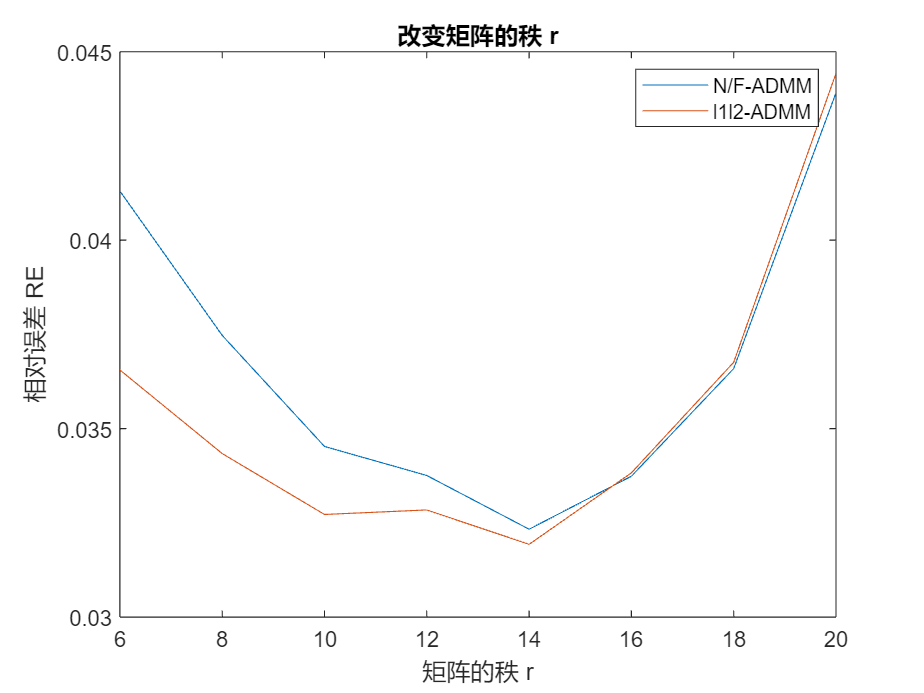

% plot for r (svt, wnnm, splp)
plot(r_vec, re_r_nf_vec(:, 1))
hold on
plot(r_vec, re_r_l1l2_vec(:, 1))
hold off
title("改变矩阵的秩 r")
xlabel("矩阵的秩 r")
ylabel("相对误差 RE")
legend("N/F-ADMM", "l1l2-ADMM")
saveas(gcf, 're-r-l1l2', 'jpg');

plot for r time

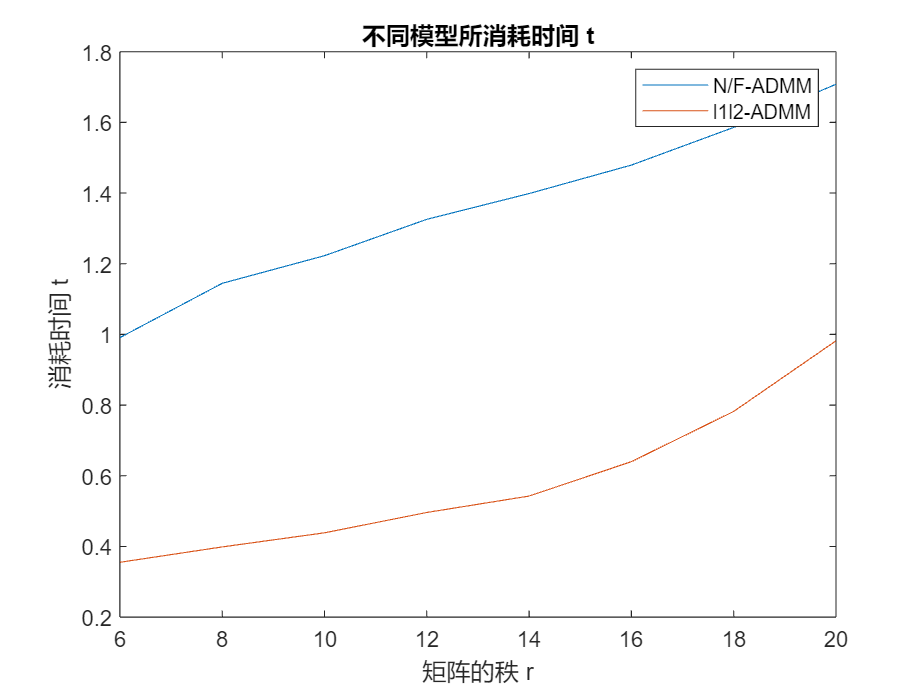

plot(r_vec, time_r_nf_vec)
hold on
plot(r_vec, time_r_l1l2_vec)
hold off
title("不同模型所消耗时间 t")
xlabel("矩阵的秩 r")
ylabel("消耗时间 t")
legend("N/F-ADMM", "l1l2-ADMM")
saveas(gcf, 't-r-l1l2', 'jpg');

check

re_r_nf_vec

re_r_nf_vec =     0.0413    0.0022
    0.0375    0.0020
    0.0345    0.0014
    0.0338    0.0011
    0.0323    0.0010
    0.0337    0.0008
    0.0366    0.0016
    0.0439    0.0027


re_r_l1l2_vec

re_r_l1l2_vec =     0.0366    0.0018
    0.0343    0.0016
    0.0327    0.0014
    0.0328    0.0010
    0.0319    0.0011
    0.0338    0.0006
    0.0368    0.0014
    0.0444    0.0026


3. change sr

%% 3. change sr
% re_sr_**_vec stores the average value(re) of ** for different sr
% 9 below means there are 9 different srs
re_sr_nf_vec = zeros(9, 2);
re_sr_l1l2_vec = zeros(9, 2);

% time
time_sr_nf_vec = zeros(9, 1);
time_sr_l1l2_vec = zeros(9, 1);

% index indicates the index of current sr_change
index = 1;

% fun for different sr_changes
for sr_change = 0.5: 0.05: 0.9
    sr_change
    index

    % define re_**_vec
    re_nf_vec = zeros(repeat, 1);
    re_l1l2_vec = zeros(repeat, 1);
    
    % repeat, return the vec
    for i = 1 : repeat
    
        % generating matrix
        L = normrnd(0, 1, n1, r);
        R = normrnd(0, 1, n2, r);
        N = normrnd(0, 1, n1, n2);
        X = L * R' + mu * N;
        
        % sampling matrix(support)
        support = ones(n1, n2);
        Ind = randperm(n1 * n2);
        
        %number of missing values
        EL0 = round(n1 * n2 * (1 - sr_change));
        
        %random EL0 elements would be set to 0
        support(Ind(1:EL0)) = 0;
    
        % observed matrix
        D = support .* X;
    
        % ||X||_F
        X_fro = max(norm(X, 'fro'), 1);

        %% N/F
        % experiment
        start_nf = tic;
        X_nf = NF(D, support, lembda, mu1, mu2, k_max, t_max, tol_nf);
        time_nf = toc(start_nf);
        % time
        time_sr_nf_vec(index, 1) = time_sr_nf_vec(index, 1) + time_nf;

        % re
        re_nf = norm(X_nf - X, 'fro') / X_fro;

        %fill in the re_nf_vec
        re_nf_vec(i, 1) = re_nf;

        %% l1l2
        % experiment
        start_l1l2 = tic;
        X_l1l2 = l1l2(D, support, beta_l1l2, mu_l1l2, rho_l1l2, tol, maxiter);
        time_l1l2 = toc(start_l1l2);
        % time
        time_sr_l1l2_vec(index, 1) = time_sr_l1l2_vec(index, 1) + time_l1l2;

        % re
        re_l1l2 = norm(X_l1l2 - X, 'fro') / X_fro;

        % fill in the re_l1l2_vec
        re_l1l2_vec(i, 1) = re_l1l2;

    end

    % fill in the average re
    re_sr_nf_vec(index, 1) = mean(re_nf_vec);
    re_sr_l1l2_vec(index, 1) = mean(re_l1l2_vec);

    % fill in ites std
    re_sr_nf_vec(index, 2) = std(re_nf_vec);
    re_sr_l1l2_vec(index, 2) = std(re_l1l2_vec);

    % normalization for time
    time_sr_nf_vec(index, 1) = time_sr_nf_vec(index, 1) / repeat;
    time_sr_l1l2_vec(index, 1) = time_sr_l1l2_vec(index, 1) / repeat;

    % update index
    index = index + 1;
end

sr_change = 0.5000

index = 1

sr_change = 0.5500

index = 2

sr_change = 0.6000

index = 3

sr_change = 0.6500

index = 4

sr_change = 0.7000

index = 5

sr_change = 0.7500

index = 6

sr_change = 0.8000

index = 7

sr_change = 0.8500

index = 8

sr_change = 0.9000

index = 9

plot for sr (svt, wnnm, splp)

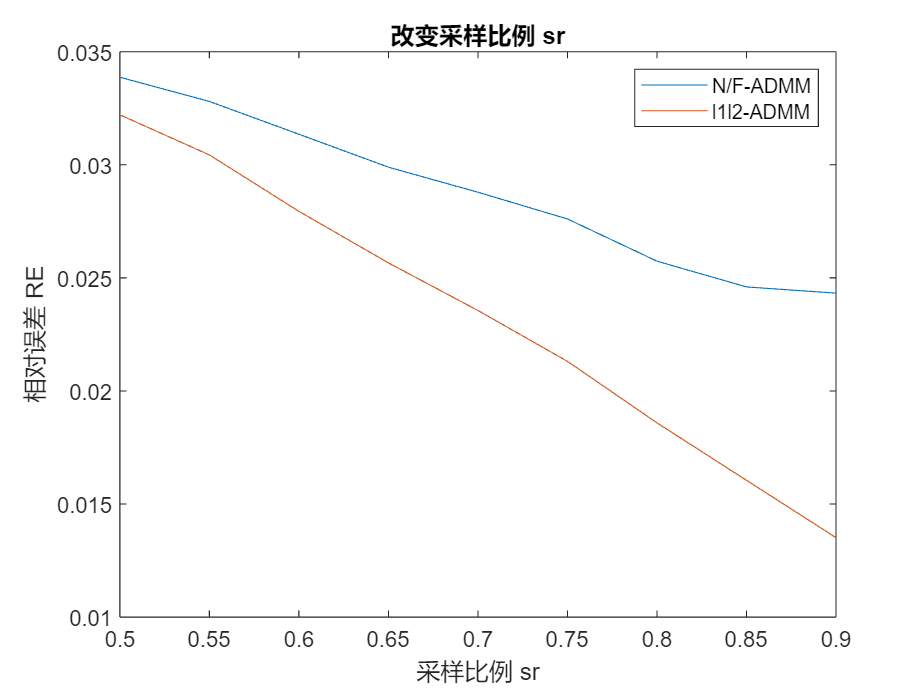

plot(sr_vec, re_sr_nf_vec(:, 1))
hold on
plot(sr_vec, re_sr_l1l2_vec(:, 1))
hold off
title("改变采样比例 sr")
xlabel("采样比例 sr")
ylabel("相对误差 RE")
legend("N/F-ADMM", "l1l2-ADMM")
saveas(gcf, 're-sr-l1l2', 'jpg');

plot for sr time

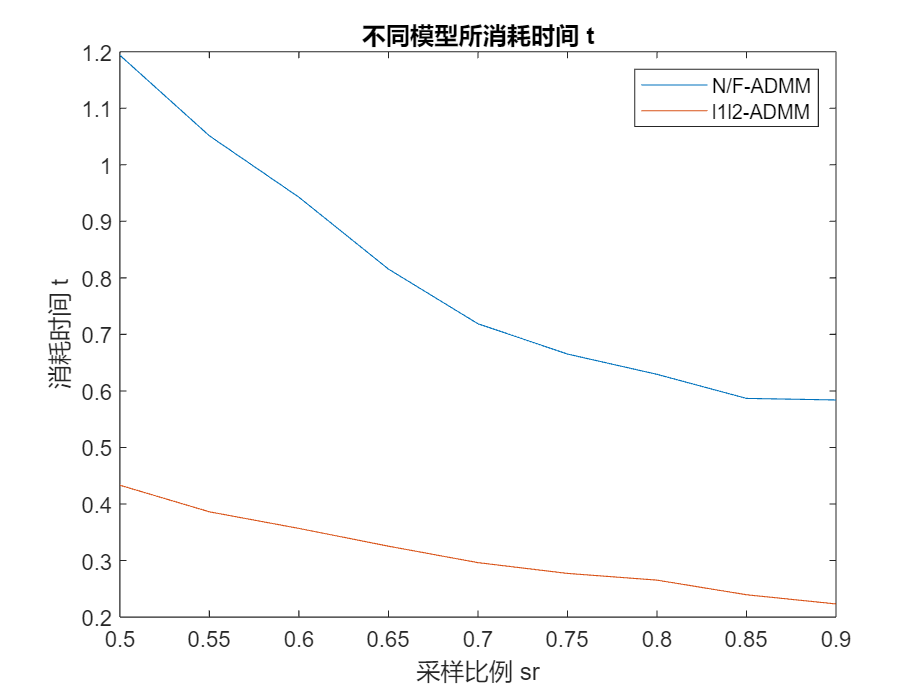

plot(sr_vec, time_sr_nf_vec)
hold on
plot(sr_vec, time_sr_l1l2_vec)
hold off
title("不同模型所消耗时间 t")
xlabel("采样比例 sr")
ylabel("消耗时间 t")
legend("N/F-ADMM", "l1l2-ADMM")
saveas(gcf, 't-sr-l1l2', 'jpg');

check

re_sr_nf_vec

re_sr_nf_vec =     0.0339    0.0009
    0.0328    0.0017
    0.0314    0.0018
    0.0299    0.0011
    0.0288    0.0008
    0.0276    0.0017
    0.0257    0.0011
    0.0246    0.0011
    0.0243    0.0009


re_sr_l1l2_vec

re_sr_l1l2_vec =     0.0322    0.0008
    0.0304    0.0014
    0.0279    0.0012
    0.0257    0.0008
    0.0236    0.0006
    0.0213    0.0010
    0.0186    0.0006
    0.0160    0.0005
    0.0135    0.0005
